# **MEC4127F: Introduction to Robotics**

# Chapter 4: Pose estimation

## 4.1 Introduction

**Chapter 2** and **Chapter 3** have provided the mathematical framework to understand rigid bodies in motion, as well as how to describe their position and orientation when in motion. **Chapter 4 **builds on this foundational knowledge and begins to explore practical uses of the underlying theory. Pose estimation is an important field in robotics — it underpins any robotic mission, as one cannot achieve any high-level task without having sufficiently accurate knowledge of the robot's current position and orientation. 

We will mainly explore orientation estimation in this chapter, a subfield of pose estimation, with the hopes of exposing simple yet powerful approaches to estimating the attitude of a robot given low-cost sensors. There are admittedly a wide range of sensors that can be used on robots, which are fit-for-purpose. We will, however, only focus on inertial measurement units in this course — a robust, low-cost, and commonly used approach in almost all robotic applications. That being said, many of the concepts explored here can be abstracted to other sensor modules and systems.

## 4.2 Inertial measurement units

**Inertial measurement units** (IMUs) are popular choices for use in robotics based on their exceedingly low price point, versatility, and footprint. Modern IMUs used in robotic applications usually take the form of micro-electromechanical systems (MEMS). Our smart phones, for example, all have MEMS IMUs that assist when using navigation apps. An example of an affordable IMU is shown in Figure 4.1 below.

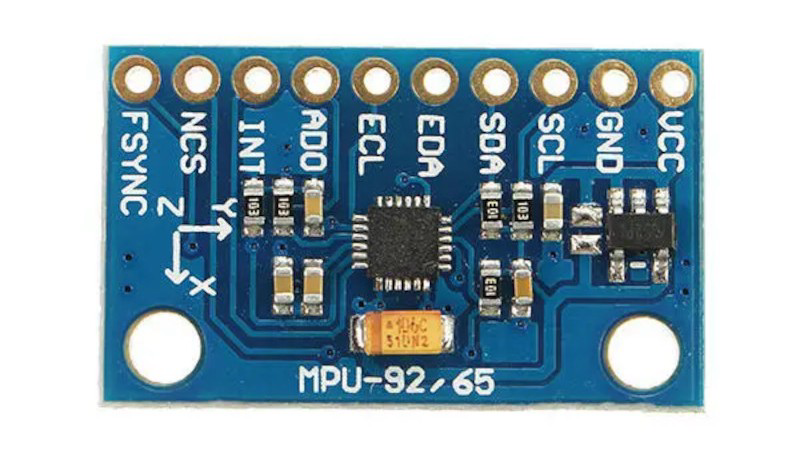

**Figure 4.1: **An MPU-9250 MEMS IMU with a breakout board [[7]](https://make.net.za/product/mpu9250-9-axis-imu-module/).

IMU modules usually comprise the following sensors:

- **Gyroscopes** — comprising three perpendicular sensors, able to measure angular velocity in the IMU frame.

- **Accelerometers** — comprising three pependicular sensors, able to measure the sum of translational and gravitational acceleration in the IMU frame.

- **Magnetometers** — comprising three pependicular sensors, able to measure the earth's magnetic field intensity in the IMU frame.

- **Temperature** **sensor** — comrprising a single sensor, able to measure the temperature of the IMU.

Some IMU modules also include a barometer, which can roughly infer altitude using pressure as a measurement. We will discuss these sensors in detail in the following subsections.

Sensors within an inertial measurement unit have the same general structure of


$${\bf x}^\#={\bf S}{\bf x}+{\bf b}+{\bf n},$$


where ${\bf x}\in \mathbb{R}^3$ is the true signal, ${\bf x}^\#$ is the measurement from the sensor, $\bf S \in \mathbb{R}^{3\times 3}$ is an unknown scale factor, $\bf b$ is a time-varying bias, and $\bf n$ is random, zero-mean noise. Modern sensors are usually sold with pre-calibrated scale factors, implying ${\bf S}\approx {\bf I}$, with a quoted tolerance in the datasheet. We will assume in this course that ${\bf S}={\bf I}$ to keep things a bit simpler. Bias term ${\bf b}$ is often temperature dependant and can either be precompensated for if a temperature measurement is available on the IMU, or estimated in real-time, as we will shown in the latter sections. Noise term $\bf n$ is non-deterministic, meaning that we cannot ever measure it in any useful way. However, we will show in this Chapter how sensor fusion (combining measurements from multiple sensors) can be used to circumvent problematic noise levels.

### 4.2.1 Gyroscopes

Any sensor that measures the rate of change of orientation is known as a gyroscope. The gyroscope found in an IMU provides a convenient measure of rotational velocity. If the sensor is correctly calibrated, the measurement is very reliable and can often be provided at high sampling rates of over $1$kHz. As we will show in the following subsections, gyroscopes struggle when estimating orientation over time due to an effect known as drift — the result of accumulated integration error. 

#### 4.2.1.1 Measurement equation

Assuming the IMU frame is aligned with $\{B\}$, the generalised measurement equation of a gyroscope is given by


$${^B{\bf \omega}^\#}={^B{\bf \omega}}+{\bf b}_\omega+{\bf n}_\omega,$$


where ${^B{\bf \omega}}$ is the true angular velocity experienced by the sensor (and by extension, frame $\{B\}$), ${^B{\bf \omega}^\#}$ is the measured signal, with the superscript $\#$ indicating a measured quantity, ${{\bf b}_\omega}$ is an unknown and time-varying bias term, and ${{\bf n}_\omega}$ is nondeterministic measurement noise, which is often treated as white noise.

#### 4.2.1.2 Bias compensation

The unknown bias term of ${{\bf b}_\omega}$ needs to be accounted for when estimating angular velocity. Angular velocity bias is temperature dependant and has an approximately linear relationship with incremental changes in temperature. For this reason, most MEMS IMUs also include temperature sensing modules to actively account for this. The bias term can be approximately inferred from IMU temperature based on


$${{\bf b}^+_\omega} =  {{\bf b}_\omega}(0)+{\bf c} \Delta T^\#,$$


where ${{\bf b}^+_\omega} $ is the estimated bias term, with the superscript of $+$ indicating the parameter is an estimate, ${{\bf b}_\omega}(0)$ is the initial bias term at time $t=0$, ${\bf c}$ is a vector of gradient coefficients, and $\Delta T^\#$ is the measured differential temperature on the IMU.

If the IMU is constrained such that angular velocity is not experienced, ${^B{\bf \omega}^}={\bf 0}$, the measurement equation becomes


$$\begin{array}{ll}
{^B{\bf \omega}^\#}
&={\bf b}_\omega+{\bf n}_\omega,\\
&\approx {{\bf b}_\omega}(0)+{\bf c} \Delta T^\#+{\bf n}_\omega.
\end{array}$$


In this configuration, as the gyroscope experiences an increase of temperate, a corresponding straight line response will be seen on each channel of the gyroscope, with the respective y-intercepts corresponding to ${{\bf b}_\omega}(0)$, and the gradients corresponding to the elements of $\bf c$. One can therefore *de-bias* the gyroscope reading using ${{\bf b}_\omega^+}$ if the sensor has been calibrated, which yields an estimate for the angular velocity of


$$\begin{array}{ll}
{^B{\bf \omega}^+}
&={^B{\bf \omega}^\#}-{{\bf b}^+_\omega},\\
&={^B{\bf \omega}}+\left({\bf b}_\omega-{{{\bf b}^+_\omega}}\right)+{\bf n}_\omega, \\
&\approx{^B{\bf \omega}}+{\bf n}_\omega.
\end{array}$$


#### Example: Calibrating a gyroscope

The code block below provides a simulated example of the effects of gyroscope bias, as well as how to actively compensate for it.

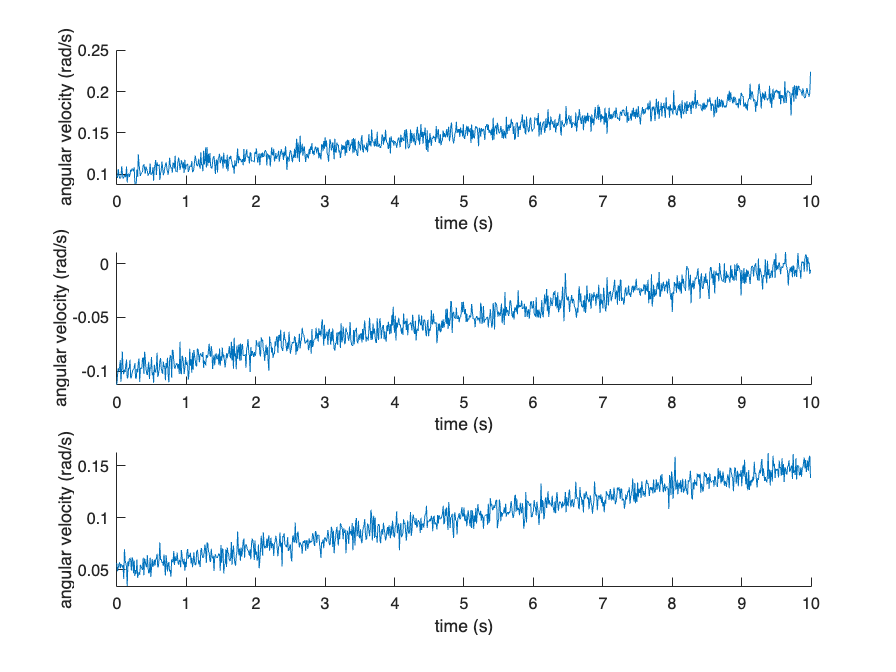

IMU = imuSensor;    %initialise simulated IMU
IMU.Gyroscope.NoiseDensity = 1e-3;    %set gyroscope noise density
IMU.Gyroscope.ConstantBias = [0.1 -0.1 0.05];    %set gyroscope bias
IMU.Gyroscope.TemperatureBias = 1e-3*ones(1,3);    %set gyroscope temperature gradient
IMU.Temperature = 25;    %set initial IMU temperature

dT = 0.01;    %sampling duration
numSamples = 1000;    %number of samples
t = (0:numSamples-1)*dT;    %time vector

omega = zeros(1,3);    %zero angular velocity
omege_meas = zeros(numSamples,3);    %initialised measured angular velocity 
temp = zeros(numSamples,1);

for k=1:numSamples
    [~,omega_meas(k,:)] = IMU(zeros(1,3),omega);    %generate simulated gyroscope measurements using IMU
    temp(k) = IMU.Temperature;                      %save current IMU temperate
    IMU.Temperature = IMU.Temperature+0.1;          %increase IMU temperature by 0.1 degrees
end

%plot figure
figure,
subplot(3,1,1), hold on
plot(t,omega_meas(:,1)),xlabel('time (s)'),ylabel('angular velocity (rad/s)')
subplot(3,1,2),hold on
plot(t,omega_meas(:,2)),xlabel('time (s)'),ylabel('angular velocity (rad/s)')
subplot(3,1,3),hold on
plot(t,omega_meas(:,3)),xlabel('time (s)'),ylabel('angular velocity (rad/s)')

We can fit a straight line to this data using MATLAB (or roughly by hand), which gives the following behaviour.

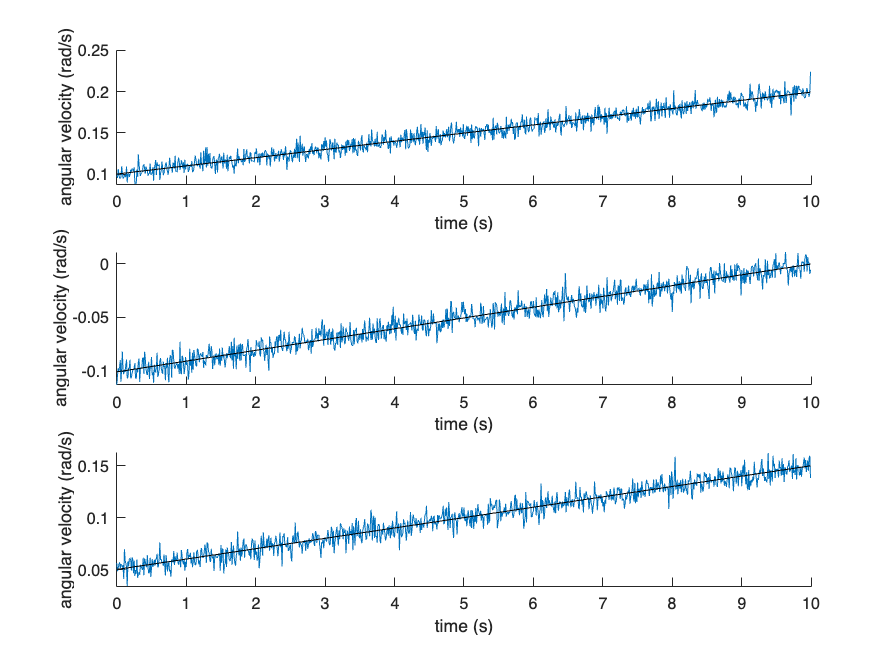

p1 = polyfit(temp-temp(1),omega_meas(:,1),1);    %fit first-order polynomial to angular velocity data
p2 = polyfit(temp-temp(1),omega_meas(:,2),1);
p3 = polyfit(temp-temp(1),omega_meas(:,3),1);

b = zeros(numSamples,3);                         %initialise bias vector
b(:,1) = p1(2)+p1(1)*(temp-temp(1));             %determine bias estimate using polynomial coefficients
b(:,2) = p2(2)+p2(1)*(temp-temp(1));
b(:,3) = p3(2)+p3(1)*(temp-temp(1));

%plot figure
figure,
subplot(3,1,1), hold on
plot(t,omega_meas(:,1)),xlabel('time (s)'),ylabel('angular velocity (rad/s)')
plot(t,b(:,1),'k')
subplot(3,1,2),hold on
plot(t,omega_meas(:,2)),xlabel('time (s)'),ylabel('angular velocity (rad/s)')
plot(t,b(:,2),'k')
subplot(3,1,3),hold on
plot(t,omega_meas(:,3)),xlabel('time (s)'),ylabel('angular velocity (rad/s)')
plot(t,b(:,3),'k')

Using $\begin{array}{ll}
{^B{\bf \omega}^+}
&={^B{\bf \omega}^\#}-{{\bf b}^+_\omega}
\end{array}$, we can plot the resulting estimated angular velocity, which we know should be equal to zero.

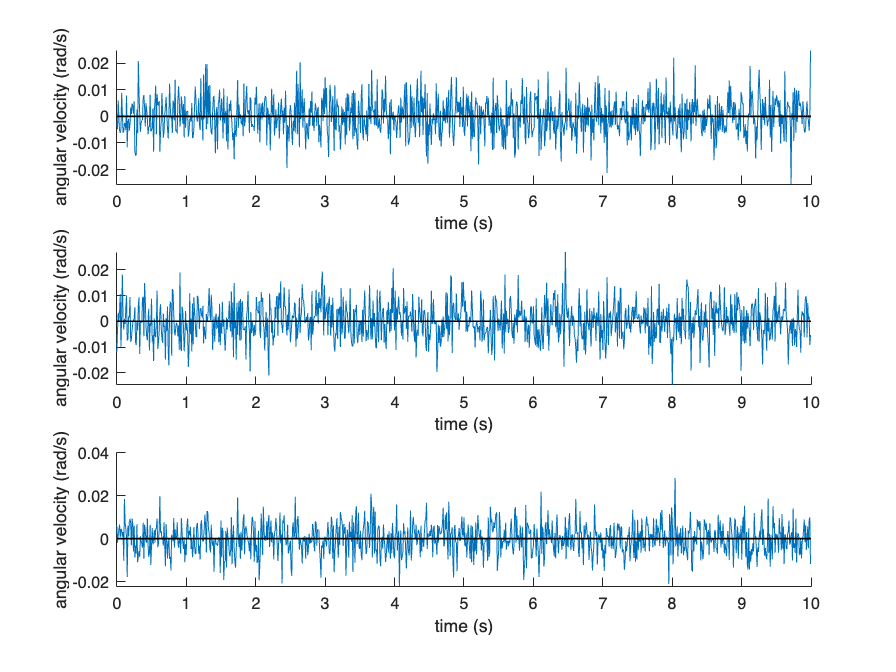

%plots of angular velocity after measurement has been de-biased
figure,
subplot(3,1,1), hold on
plot(t,omega_meas(:,1)-b(:,1)),xlabel('time (s)'),ylabel('angular velocity (rad/s)')
line(xlim, [0,0], 'Color', 'k', 'LineWidth', 1); % Draw line for X axis.
subplot(3,1,2),hold on
plot(t,omega_meas(:,2)-b(:,2)),xlabel('time (s)'),ylabel('angular velocity (rad/s)')
line(xlim, [0,0], 'Color', 'k', 'LineWidth', 1); % Draw line for X axis.
subplot(3,1,3),hold on
plot(t,omega_meas(:,3)-b(:,3)),xlabel('time (s)'),ylabel('angular velocity (rad/s)')
line(xlim, [0,0], 'Color', 'k', 'LineWidth', 1); % Draw line for X axis.

While noise is still present, the bias term has clearly been removed.

#### 4.2.1.3 Estimating orientation using rotation matrices

Recall from **Chapter 3** that if the angular velocity is exactly known for a period of $\Delta t$ units of time, the incremental exponential coordinates are given by


$${^B\Delta{\bf \theta}={^B{\bf \omega}}\Delta t.$$


The incremental axis-angle form was given by


$$\Delta \alpha=|{^B{\bf \omega}}|\Delta t,$$
           
$${^B\hat{\bf \omega}}=\frac{^B{\bf \omega}}{|{^B{\bf \omega}}|},$$


and the corresponding incremental rotation matrix was


$$\begin{array}{ll}
\Delta{\bf R}
&=\mathrm{e}^{\lfloor {^B{\Delta\bf \theta}} \rfloor},\\
&=\mathrm{e}^{\lfloor {^B{\bf \omega}}\Delta t \rfloor},\\
&={\bf I}+\sin\Delta\alpha\lfloor ^B\hat{\bf \omega} \rfloor +\left(1-\cos\Delta\alpha\right)\lfloor ^B\hat{\bf \omega} \rfloor^2,\\
&={\bf I}+\sin(|{^B{\bf \omega}}|\Delta t)\lfloor ^B\hat{\bf \omega} \rfloor +\left(1-\cos(|{^B{\bf \omega}}|\Delta t)\right)\lfloor ^B\hat{\bf \omega} \rfloor^2.
\end{array}
$$


Assuming that the angular velocity measurement has been sufficiently de-biased, one can similarly integrate ${^B{\bf \omega}^+}$ to obtain an orientation *estimate*. Replacing ${^B{\bf\omega}}$ with ${^B{\bf\omega}^+}$ for the above equations yields


$${^B\Delta{\bf \theta}^+={^B{\bf \omega}^+}\Delta t,$$
     
$$\Delta \alpha^+=|{^B{\bf \omega}^+}|\Delta t,$$
      
$${^B\hat{\bf \omega}^+}=\frac{^B{\bf \omega}^+}{|{^B{\bf \omega}^+}|},$$


and 


$$\begin{array}{ll}
\Delta{\bf R}^+
&=\mathrm{e}^{\lfloor {^B{\Delta{\bf \theta}^+}} \rfloor},\\
&=\mathrm{e}^{\lfloor {^B{\bf \omega}^+}\Delta t \rfloor},\\
&={\bf I}+\sin\Delta\alpha^+\lfloor ^B\hat{\bf \omega}^+ \rfloor +\left(1-\cos\Delta\alpha^+\right)\lfloor ^B\hat{\bf \omega}^+ \rfloor^2,\\
&={\bf I}+\sin(|{^B{\bf \omega}^+}|\Delta t)\lfloor ^B\hat{\bf \omega}^+ \rfloor +\left(1-\cos(|{^B{\bf \omega}^+}|\Delta t)\right)\lfloor ^B\hat{\bf \omega}^+ \rfloor^2.
\end{array}
$$


An estimated angular velocity experienced by a rigid body that moves it from frame $\{0\}$ to $\{1\}$ over a period of $\Delta t$ units is then described by


$${^W{\bf R}^+_{\{1\}}}={^W{\bf R}^+_{\{0\}}}{^{\{0\}}{\bf R}^+_{\{1\}},$$
 

where $\Delta{\bf R}^+={^{\{0\}}{\bf R}^+_{\{1\}}
$ is the incremental orientation as a result of the body-frame angular velocity. 

In practice, angular velocity measurements will be obtained from a gyroscope at discrete intervals, as opposed to being a continuous signal. If we make the assumption that the angular velocity is constant during each sampling instance of length $\Delta t$, then we can define our incremental rotation at sample time $k$ as 


$$\begin{array}{ll}
\Delta{\bf R}^+_k
&={^{\{k-1\}}{\bf R}_{\{k\}},\\
&=\mathrm{e}^{\lfloor {^B{\bf \omega}^+_k}\Delta t \rfloor},\\
&={\bf I}+\sin\Delta\alpha^+_k\lfloor ^B\hat{\bf \omega}^+_k \rfloor +\left(1-\cos\Delta\alpha^+_k\right)\lfloor ^B\hat{\bf \omega}^+_k \rfloor^2,\\
&={\bf I}+\sin(|{^B{\bf \omega}^+_k}|\Delta t)\lfloor ^B\hat{\bf \omega}^+_k \rfloor +\left(1-\cos(|{^B{\bf \omega}^+_k}|\Delta t)\right)\lfloor ^B\hat{\bf \omega}^+_k \rfloor^2.
\end{array}
$$


The estimated orientation at sample instance $k$ follows as


$$\begin{array}{ll}
{^W{\bf R}^+_{\{k\}}}
&={^W{\bf R}^+_{\{0\}}}{^{\{0\}}{\bf R}^+_{\{1\}} \dots {^{\{k-1\}}{\bf R}^+_{\{k\}},\\
&={^{W}{\bf R}^+_{\{k-1\}} {^{\{k-1\}}{\bf R}^+_{\{k\}},\\
\end{array}$$
 

where each rotation matrix estimate is obtained from a particular sampling instance, after integrating the angular velocity and then applying the exponential coordinate mapping. 

The angular velocity estimate ${^B{\bf \omega}^+}$ is notably imperfect, as a result of 

- non-zero sensor resolution (from the ADC conversion), 

- noise term ${\bf n}_\omega$, 

- as well as the potential biasing as a result of ${{{\bf b}^+_\omega}}\neq{\bf b}_\omega$. 

Additionally, the assumption that the estimated angular velocity is constant for the entire duration of the sampling period will also result in an imperfect estimate of the incremental exponential coordinates, based on ${^B\Delta{\bf \theta}^+={^B{\bf \omega}^+}\Delta t$. For this reason, the orientation estimate using the approach outlined above will ultimately experience drift (or random walk) that cannot be compensated for. The result is that the orientation estimate will become less reliable over time, as the errors from the imperfect angular velocity estimate and sampling assumptions continue to accumulate. This problem can be solved using sensor fusion, which is introduced in Section 4.4.

#### 4.2.1.4 Estimation orientation using quaternions

As shown in **Chapter 3**, The quaternion is an alternative approach to determining orientation from angular velocity information. Given an angular velocity estimate of ${^B{\bf \omega}^+_k}$ at sample instance $k$, the angle-axis representation of the incremental rotation can be determined by


$$\Delta \alpha^+_k=|{^B{\bf \omega}^+_k}|\Delta t,$$
      
$${^B\hat{\bf \omega}^+_k}=\frac{^B{\bf \omega}^+_k}{|{^B{\bf \omega}^+_k}|},$$


which is equivalent to the axis-angle representation of the incremental exponential coordinates in Section 4.2.1.3. The estimated incremental quaternion at sample instance $k$ follows as


$$\begin{array}{cc}\Delta{\mathbf q}^+_k =
{^{\{k-1\}}{\bf q}^+_{\{k\}}
= \left[\begin{array}{cc}    \cos{\frac{\Delta\alpha^+_k}{2}} \\ \sin{\frac{\Delta\alpha^+_k}{2}} {^B\hat{\mathbf \omega}^+_k}     \\ \end{array}\right],\end{array}$$


with the absolute estimated quaternion given by


$$\begin{array}{ll}
{^W{\bf q}^+_{\{k\}}}
&={^W{\bf q}^+_{\{0\}}}\otimes{^{\{0\}}{\bf q}^+_{\{1\}}\otimes \dots \otimes{^{\{k-1\}}{\bf q}^+_{\{k\}}, \\
&={^W{\bf q}^+_{\{k-1\}}} \otimes{^{\{k-1\}}{\bf q}^+_{\{k\}}.
\end{array}$$
 

As with the rotation matrix approach, estimating the quaternion orientation using only estimated (and imperfect) angular velocity information will result in orientation errors over time.

#### Example: Estimating orientation from a gyroscope

The code block below provides a simulation of an IMU with adjustable noise. With negligible noise, the orientation estimates are reliable over the full length of the simulation, but with increasing noise the accuracy drops significantly.

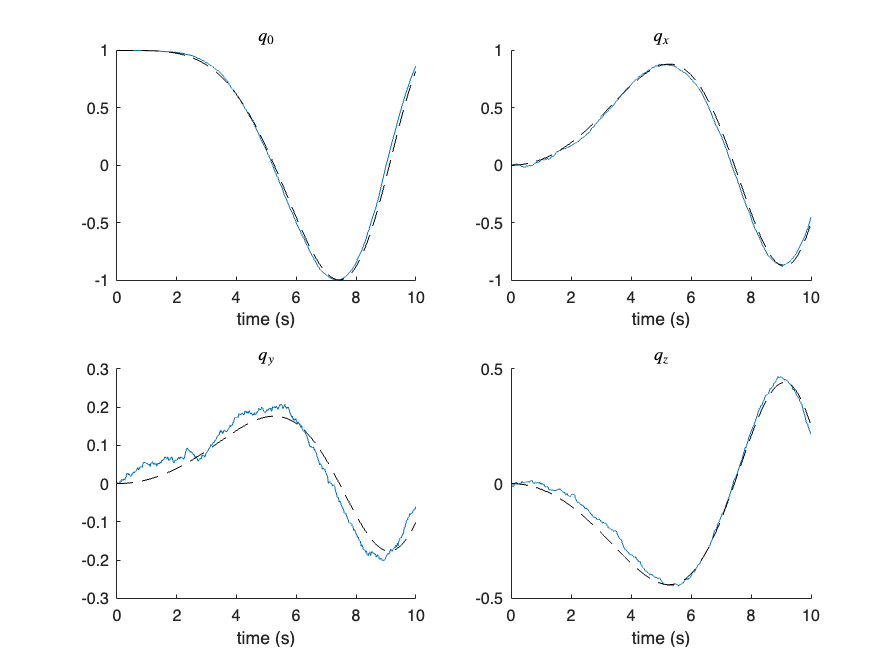

IMU = imuSensor;    %initialise simulated IMU
IMU.Gyroscope.NoiseDensity = 0.03301;    %set gyroscope noise density
dT = 0.01;    %set sampling time
numSamples = 1000;    %set number of samples
t = (0:numSamples-1)*dT;    %set time vector

omega1 = linspace(0,1,numSamples);
omega2 = linspace(0,0.2,numSamples);
omega3 = linspace(0,-0.5,numSamples);
omega = [omega1' omega2' omega3'];    %define arbitrary angular velocity


q_ = zeros(numSamples,4);    %initialise estimated quaternion array
q_(1,1:4) = [1 0 0 0];
q = q_;

for k=1:numSamples-1
    %actual
    dtheta = omega(k,:)*dT;    %incremental exponential coordinates
    dalpha = norm(dtheta);     %incremental rotation angle
    if( dalpha == 0)           %incremental rotation vector
        v = [0 0 0];
    else
        v = dtheta/dalpha;
    end
    dq = [cos(dalpha) sin(dalpha)*v];    %incremental quaternion
    q(k+1,1:4) = quatmultiply(q(k,1:4),dq);    %update quaternion
    q(k+1,1:4) = q(k+1,1:4)/norm( q(k+1,1:4) );


    %estimate
    [~,omega_meas] = IMU(zeros(1,3),omega(k,:));    %obtain simulated gyroscope reading
    dtheta_ = omega_meas*dT;    %estimated incremental exponential coordinates
    dalpha_ = norm(dtheta_);    %estimated incremental rotation angle
    if( dalpha_ == 0 )          %estimated incremental rotation vector
        v_ = [0 0 0];
    else
        v_ = dtheta_/dalpha_;
    end
    dq_ = [cos(dalpha_) sin(dalpha_)*v_];    %estimated incremental quaternion
    q_(k+1,1:4) = quatmultiply(q_(k,1:4),dq_);    %update estimated quaternion
    q_(k+1,1:4) = q_(k+1,1:4)/norm( q_(k+1,1:4) );
end

%plot figure
figure
subplot(2,2,1),hold on
plot(t,q_(:,1)),plot(t,q(:,1),'--k'),title('$q_0$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,2),hold on
plot(t,q_(:,2)),plot(t,q(:,2),'--k'),title('$q_x$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,3),hold on
plot(t,q_(:,3)),plot(t,q(:,3),'--k'),title('$q_y$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,4),hold on
plot(t,q_(:,4)),plot(t,q(:,4),'--k'),title('$q_z$',Interpreter='latex'),xlabel('time (s)')

### 4.2.2 Accelerometers

Accelerometers are sensors that measure acceleration, albeit indirectly. Even when not moving they sense the acceleration due to gravity, which defines the direction we know as upward. Gravitational acceleration is a function of the material in the Earth beneath us and our distance from the Earth’s center. 

As we will show in the following subsections, we can either use an accelerometer to (partially) estimate orientation when there is no translational acceleration, or estimate translational acceleration when the orientation is sufficiently well known. We cannot simultaneously estimate both since there are more unknowns than measurements.

#### 4.2.2.1 Measurement equation

The generalised measurement equation of an accelerometer is given by


$${^B{\bf a}^\#}={^B{\bf a}}+{^B{\bf g}}+{\bf b}_a+{\bf n}_a,$$


where ${^B{\bf a}}$ is the true translational acceleration experienced by the sensor (and by extension, the frame $\{B\}$ centre of mass), $^B{\bf g}$ is the gravitational acceleration vector in $\{B\}$, ${{\bf b}_a}$ is an unknown and possibly time-varying bias term, and ${{\bf n}_a}$ is nondeterministic measurement noise, which is often treated as white noise.

We also know that the gravitational acceleration in $\{W\}$ is given by $^W{\bf g}=[0~0~g]^T$, with $g\approx 9.8$m/s$^2$ (in Cape Town, South Africa). The relationship between the gravitational acceleration in the two frames is simply


$${^B{\bf g}}= {^B{\bf R}_W}{^W{\bf g}},$$


which means that we require knowledge of the orientation when relating the two vectors.

#### 4.2.2.2 Bias compensation

Accelerometers often have constant and slowly time-varying biases that are fairly insensitive to temperate changes. As such, it is often sufficient to just determine the constant bias offset instead if the sensor will be used for short periods of time. In the absence of translational acceleration (${^B{\bf a}}=0$), the accelerometer equation is given by


$${^B{\bf a}^\#}={^B{\bf g}}+{\bf b}_a+{\bf n}_a.$$


The approximately constant bias term can then be estimated based on


$$\begin{array}{ll}
{\bf b}^+_a
&\approx {^B{\bf a}^\#}-{^B{\bf g}},\\
&\approx {^B{\bf a}^\#}-{^W{\bf R}_B}{^W{\bf g}},
\end{array}$$


if the orientation is known sufficiently accurately, for example from a gimballed rig that can measure orientation using encoders/potentiometers. Other calibration procedures exist that do not require knowledge of the orientation, but this will not be explored in this course. Notably, if the above approach is not sufficient for long-term operation of the robot, the process outlined in Section 4.2.1.2 can be retailored for use with an accelerometer.

#### 4.2.2.3 Estimating orientation

Orientation can be partially estimated using an accelerometer if translational acceleration is negligible. Recall that the acceleration model with ${^B{\bf a}}\approx0$ and ${\bf b}^+_a\approx{\bf b}_a$ is given by


$$\begin{array}{ll}
{^B{\bf a}^\#}
&\approx{^B{\bf g}}+{\bf n}_a,\\
&\approx{^B{\bf R}_W}{^W{\bf g}}+{\bf n}_a.\\
\end{array}$$


Recall that the cross product of two unitary vectors is given by


$$\hat{\bf a}\times \hat{\bf b}=\sin{\theta} \hat{\bf c},$$


where $\theta$ describes the angle between vectors $\hat{\bf a}$ and $\hat{\bf b}$, and $\hat{\bf c}$ defines the vector perpendicular to $\hat{\bf a}$ and $\hat{\bf b}$. Additionally, it was shown that if we were to rotate vector $\hat{\bf a}$ about vector $\hat{\bf c}$ with a rotation of $\theta$ units, we would obtain $\hat{\bf b}$, namely


$$\begin{array}{ll}
\hat{\bf b}
&={\bf R}\hat{\bf a},\\
&={\bf e}^{\lfloor\theta\hat{\bf c}\rfloor}\hat{\bf a}.\\
\end{array}$$


We can use this formulation to determine the rotation matrix that maps the gravity vector in $\{B\}$ onto that of $\{W\}$. We first need to normalise the accelerometer measurement, which is given by


$$\begin{array}{ll}
{^B\hat{\bf a}^\#}
&\approx\frac{^B{\bf g}}{|^B{\bf g}|},\\
&\approx {^B\hat{\bf g}},\\
&=[\hat{a}_x ~ \hat{a}_y ~ \hat{a}_z]^T.
\end{array}$$


The gravity vector described in $\{W\}$ is simply $^W\hat{\bf g}=[0~0~1]^T$. The cross product of ${^B\hat{\bf a}^\#}$ and $^W\hat{\bf g}$ follows as


$${^B\hat{\bf a}^\#}\times {^W\hat{\bf g}}=\left[\begin{array}{cc}    \hat{a}_y \\ -\hat{a}_x \\ 0     \\ \end{array}\right]=\sin{\alpha^+} {^W\hat{\bf v}^+},$$


as confirmed by the code block below.

syms a_x a_y a_z
a = [a_x a_y a_z];
cross(a,[0 0 1])

$$ans = \left(\begin{array}{ccc} a_{y} & -a_{x} & 0 \end{array}\right)$$

Notably, the $z$-axis component is always zero, which infers that the accelerometer cannot detect rotations about $\hat{\bf z}_W$. This should not be too surprising, as the gravity vector in $\{W\}$ is parallel to $\hat{\bf z}_W$. In other words, when rotating an accelerometer about $\hat{\bf z}_W$, the sensor readings do not change. This highlights the main weaknesses of accelerometers in terms of fully estimating orientation.

The axis-angle estimation can be determined to be


$$\begin{array}{ll}
\alpha^+ 
&= \cos^{-1}\left({^B\hat{\bf a}^\#}\cdot {^W\hat{\bf g}}\right),\\
& = \cos^{-1}\hat{a}_z 
\end{array}$$


and


$${^W\hat{\bf v}}^+=\frac{1}{\sin\alpha^+}\left[\begin{array}{cc}    \hat{a}_y \\ -\hat{a}_x \\ 0     \\ \end{array}\right]=\frac{1}{\sqrt{1-\hat{a}_z^2}}\left[\begin{array}{cc}    \hat{a}_y \\ -\hat{a}_x \\ 0     \\ \end{array}\right].

$$


Finally, the rotation matrix estimate can be formed from the axis-angle representation by


$${^W{\bf R}^+_B}={\bf e}^{\lfloor  {^W{\bf v}^+}\rfloor \alpha^+}.$$


The code block below generates a visualisation of the gravity vector in $\{W\}$ (left graph) and in $\{B\}$ (right graph).

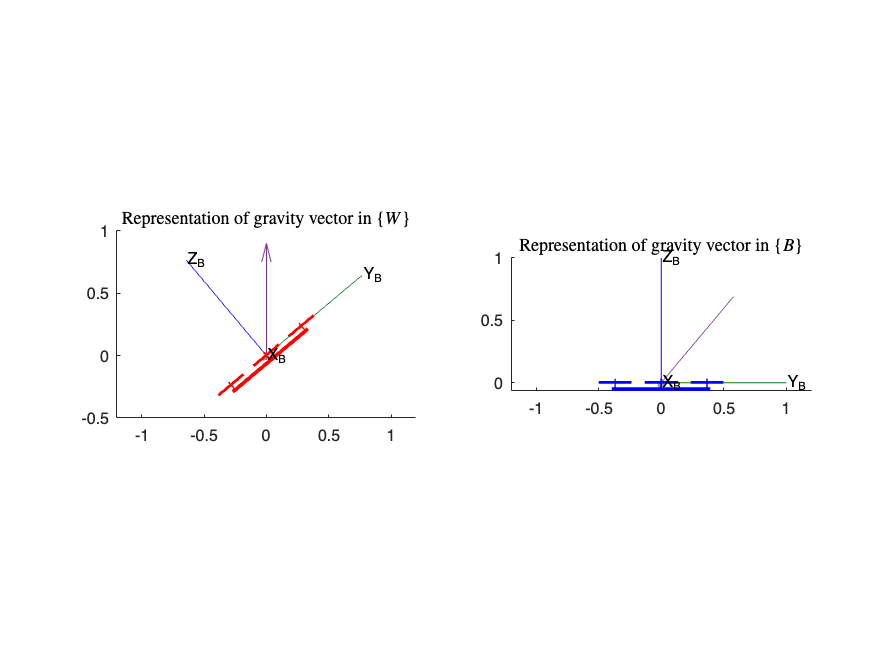

alpha = 40*pi/180;    %rotation angle
v = [1 0 0]; %rotation vector

S = [0   -v(3)  v(2);    %skew-symmetric form of rotation vector
     v(3)  0   -v(1);
    -v(2)  v(1)  0];

% R = expm(S*alpha);
R = eye(3)+sin(alpha)*S+( 1-cos(alpha) )*S^2;    %Rodrigues' formula to determine R

gb = R'*[0 0 1]';

%plot figures
figure 
subplot(1,2,1),hold on
plotTransforms([0 0 0],rotm2quat(R),"MeshFilePath",'multirotor.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","B")
quiver3(0,0,0,0,0,1,MaxHeadSize=0.5)
view(v)
axis equal,title('Representation of gravity vector in $\{W\}$',Interpreter='latex')
xlim([-1.2 1.2]),ylim([-1.2 1.2])
% legend('${^W{\bf g}}$','Interpreter','latex')

subplot(1,2,2),hold on
plotTransforms([0 0 0],[1 0 0 0],"MeshFilePath",'multirotor.stl',"MeshColor","blue","FrameAxisLabels","on","FrameLabel","B")
quiver3(0,0,0,gb(1),gb(2),gb(3),MaxHeadSize=0.5)
view(v)
axis equal,title('Representation of gravity vector in $\{B\}$',Interpreter='latex')
xlim([-1.2 1.2]),ylim([-1.2 1.2])

#### Example: Estimating roll and pitch from an accelerometer

The code block below shows an example of how accelerometers can be used to partially estimate orientation. Notably, this estimation scheme is only reliable when the rotation vector ${^W{\bf v}}$ does not have a $z$ component. 

We should notice that:

- increasing the accelerometer noise density results in a noiser estimate, but the mean is still correct;

- adding a non-zero $z$-axis component to ${^W\hat{\bf v}}$ (i.e. changing parameter `vz `in the code block below) will result in an unreliable orientation estimate;

- increasing the translational acceleration causes problems in the estimation scheme, based on the assumption that the accelerometer is only detecting the gravitational vector.

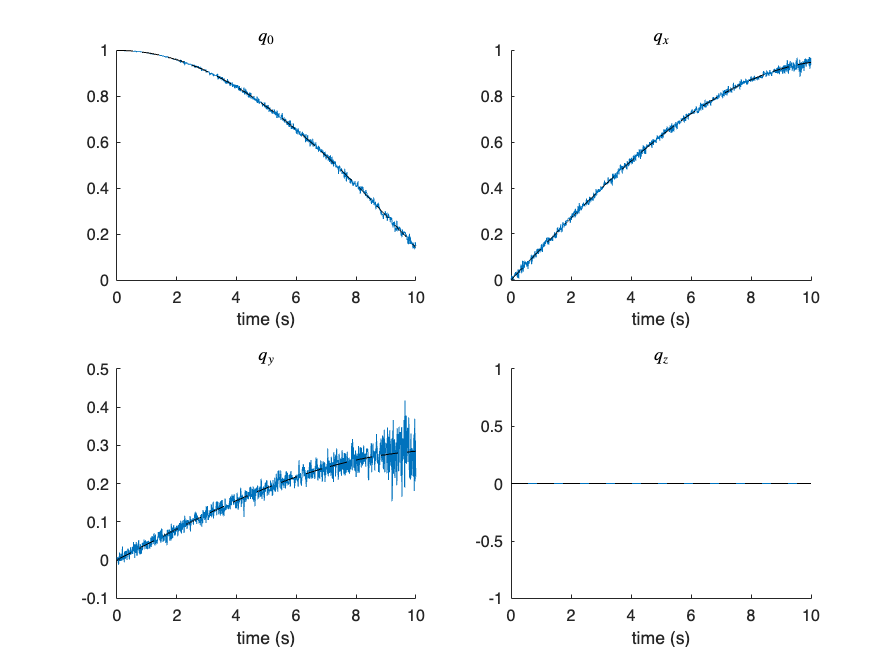

IMU = imuSensor;    %initialise simulated IMU
IMU.Accelerometer.NoiseDensity = 0.02981;    %set accelerometer noise density
acceleration = 0;

dT = 0.01;    %set IMU sample time
numSamples = 1000;    %set number of samples
t = (0:numSamples-1)*dT;    %set time vector

vx =1;    %set x component of rotation vector
vy =0.3;    %set y component of rotation vector
vz =0;    %set z component of rotation vector
v = [vx vy vz];
v = v/norm(v);    %normalise rotation vector

alpha = linspace(0,pi/1.1,numSamples);    %define array of rotation angles

q = zeros(numSamples,4);    %initialise quaternion array
q(1,1:4) = [1 0 0 0];

q_ = zeros(numSamples,4);    %initialise quaternion estimate array
q_(1,1:4) = [1 0 0 0];

gw = [0 0 1];    %gravity vector in {W}

for k=1:numSamples-1
    %actual
    q(k+1,:) = [cos(alpha(k+1)/2) sin(alpha(k+1)/2)*v];    %true quaternion

    R = quat2rotm(q(k+1,1:4));    %convert quaternion to rotation matrix

    %estimate
    [accel_meas,~] = IMU(acceleration*ones(1,3),zeros(1,3),R');    %generate accelerometer data
    accel_meas = accel_meas/norm(accel_meas);    %normalise accelerometer reading
   
    axb = cross(accel_meas,gw);    %cross product between accelerometer measurement and gravity vector in {W}
   
    % alpha_ = acos( dot(accel_meas,gw) );
    alpha_ = acos( accel_meas(3) );    %estimate rotation angle

    v_ = axb / sin( alpha_ );    %estimate rotation vector
    

    q_(k+1,1:4) = [cos(alpha_/2) sin(alpha_/2)*v_];    %estimate quaternion
    
end

%plot figures
figure
subplot(2,2,1),hold on
plot(t,q_(:,1)),plot(t,q(:,1),'--k'),title('$q_0$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,2),hold on
plot(t,q_(:,2)),plot(t,q(:,2),'--k'),title('$q_x$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,3),hold on
plot(t,q_(:,3)),plot(t,q(:,3),'--k'),title('$q_y$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,4),hold on
plot(t,q_(:,4)),plot(t,q(:,4),'--k'),title('$q_z$',Interpreter='latex'),xlabel('time (s)')

#### 4.2.2.3 Estimating translational motion

Assuming the orientation of the robot is known, we can separate out the acceleration from the accelerometer measurement. Given the de-biased measurement equation of


$${^B{\bf a}^\#}={^B{\bf a}}+{^B{\bf R}_W}{^W{\bf g}}+{\bf n}_a,$$


and known rotation matrix ${^B{\bf R}_W}$, we can estimate the translational acceleration using


$${^B{\bf a}^+}\approx{^B{\bf a}^\#}-{^B{\bf R}_W}{^W{\bf g}}.$$


The estimate of the corresponding world-frame acceleration follows as


$$\begin{array}{ll}
{^W{\bf a}^+}
&={^W{\bf R}_B}{^B{\bf a}^+},\\
&\approx {^W{\bf R}_B}\left({^B{\bf a}^\#}-{^B{\bf R}_W}{^W{\bf g}}\right),\\
&\approx {^W{\bf R}_B}{^B{\bf a}^\#}-{^W{\bf g}}.
\end{array}$$


We can then integrate this result to obtain the velocity and position estimates, namely


$${^W{\bf v}^+}(t)=\int_0^t {^W{\bf a}^+}(t)dt,$$


and


$${^W{\bf p}^+}(t)=\int_0^t {^W{\bf v}^+}(t)dt.$$


As with the orientation estimation using a gyroscope, the velocity and position estimates derived from the accelerometer will experience drift. In fact, the double integration of the estimate from acceleration to position means that the error accumulates quadratically, rather than linearly!

### 4.2.3 Magnetometers

The key element of most modern magnetometers is a Hall-effect sensor; a semiconductor device that produces a voltage proportional to the magnetic field intensity in a direction normal to the current flow. Typically three Hall-effect sensors are packaged together and arranged so that their sensitive axes are orthogonal. The three outputs of such a triaxial magnetometer are the components of the Earth’s magnetic field intensity vector measured in $\{B\}$.

Magnetometers are conceptually similar to accelerometers in that one can determine the rotation required to align a body-frame measurement of magenetic north to the world-frame counterpart. However, unlike an accelerometer, magnetometers do not measure translational accelerations, which means that the sensors can still be used to estimate orientaiton while experiencing arbitrary motion. The downside of magnetometers is that they are sensitive to electromagnetic interference, which is a natural by-product of electric motors, among other electronic devices.

#### 4.2.3.1 Measurement equation

Assuming the world-frame $x$-axis points in the direction of magnetic north, the magnetic intensity vector in $\{W\}$ is given by


$${^W{\bf m}}= B\left[\begin{array}{cc}    \cos I \\ 0 \\ \sin I     \\ \end{array}\right],$$


where $B$ is the magnetic field intensity and $I$is the inclination angle, which is dependant on where the sensor is on the earth.

The measurement equation of a magnetometer is given by


$${^B{\bf m}^\#}={^B{\bf m}}+{\bf b}_m+{\bf n}_m.$$


As with the accelerometer, the magnetometer bias term varies slowly over time and can usually be determined approximately as a constant during a calibration process. Assuming this is performed, the resulting measurement equation becomes


$${^B{\bf m}^\#}={^B{\bf m}}+{\bf n}_m.$$


#### 4.2.3.2 Estimating orientation

Orientation can be partially estimated using a magnetometer. Referring to the equation above, the measurement equation can be expressed as


$$\begin{array}{ll}
{^B{\bf m}^\#}
&={^B{\bf m}}+{\bf n}_m,\\
&={^B{\bf R}_W}{^W{\bf m}}+{\bf n}_m,\\
\end{array}$$


which takes a similar form to the accelerometer measurement model when there is no translational motion. It is common to normalise both the known magnetic intensity vector and magnetometer measurement, in order to remove the dependance on $B$:


$$\begin{array}{ll}
{^B\hat{\bf m}^\#}
&={^B\hat{\bf m}}+{\bf n}_m,\\
&={^B{\bf R}_W}{^W\hat{\bf m}}+{\bf n}_m,\\
\end{array}$$


The normalised world-frame magnetic intensity vector is given by


$${^W\hat{\bf m}}= \left[\begin{array}{cc}    \cos I \\ 0 \\ \sin I     \\ \end{array}\right],$$


which can be measured from the calibrated magnetometer when $\{B\}$ and $\{W\}$ are aligned, namely, when ${^B{\bf R}_W}={\bf I}$. 

Recalling the relationship between the cross product and exponential coordinates, as introduced in **Chapter 3**, we can determine the rotation vector and angle of rotation that in general maps ${^B\hat{\bf m}^\#}$ to ${^W\hat{\bf m}}$ using


$${^B\hat{\bf m}^\#} \times {^W\hat{\bf m} = \sin\alpha^+ \hat{\bf v}^+.$$


The exponential coordinates corresponding to the detected magnetometer rotation is given by $\alpha^+\hat{\bf v}^+$ and can be recovered using


$$\begin{array}{ll}
\alpha^+ 
&= \cos^{-1}\left({^B\hat{\bf m}^\#} \cdot {^W\hat{\bf m}}\right),
\end{array}$$


and


$${^W\hat{\bf v}}^+=\frac{1}{\sin\alpha^+} {^B\hat{\bf m}^\#} \times {^W\hat{\bf m}.

$$


Finally, the rotation matrix estimate can be formed from the axis-angle representation by


$${^W{\bf R}^+_B}={\bf e}^{\lfloor  {^W{\bf v}^+}\rfloor \alpha^+}.$$


Analogous to the accelerometer, the magnetometer cannot detect rotations about ${^W\hat{\bf m}}$. For this reason, the one cannot solely rely on a magnetometer to estimate generalised orientation.

## 4.3 Normalisation

The process of estimating orientation using rotation matrices or quaternions requires iterative multiplication of matrices or vectors, respectively. Given that the hardware (e.g. microcontroller or computer) used to make these computations has finite precision, subsequent multiplication operations, followed by numerical truncation, will eventually result in rotation matrices not being orthogonal, or quaternions not being unitary (having unit length). To compensate for this, we can perform a normalisation step at regular intervals, such as after every few samples (the frequency would depend on the numerical precision of the hardware).

### **4.3.1 Rotation matrices**

The basic concept of rotation matrix normalisation is to enforce each column of the matrix to be orthogonal to the other columns, with unit magnitudes (to preserve the orthogonal property of a rotation matrix). This is done by first selecting one column of  


$${{\mathbf R}}=[{\mathbf c}_1  ~~{\mathbf c}_2 ~~ {\mathbf c}_3]$$


such as column three, ${\mathbf c}_3$, and assume that the direction is correct, namely


$$\begin{array}{cc}    {\mathbf c}^{'}_3={\mathbf c}_3.\\ \end{array}$$


The (updated) first column, ${\bf c}_1^{'}$, is then set to be orthogonal to the last two columns


$$\begin{array}{cc}    {\mathbf c}^{'}_1={\mathbf c}_2 \times {\mathbf c}^{'}_3.\\ \end{array}$$


Given that the last two columns may not have been orthogonal, we define the second column to be orthogonal to the first and third column


$$\begin{array}{cc}    {\mathbf c}^{'}_2={\mathbf c}^{'}_3 \times {\mathbf c}^{'}_1.\\ \end{array}$$


Finally, each column is individually normalised, in order to preserve unit length


$$\begin{array}{cc}    \hat{\mathbf c}^{'}_i=\frac{ {\mathbf c}^{'}_i }{|{\mathbf c}^{'}_i|},  \forall i\in [1,3].\\ \end{array}$$


The resulting normalised rotation matrix follows as  


$${{\mathbf R}^{'}}=[\hat{\mathbf c}^{'}_1 ~~ \hat{\mathbf c}^{'}_2 ~~ \hat{\mathbf c}^{'}_3],$$


which now adheres to the othogonality requirements of SO(3).

### **4.3.2 Quaternions**

As with the rotation matrix update, we require normalisation of the quaternion in order to maintain the unitary structure. In the case of the quaternion, normalisation simply requires dividing all elements by the quaternion norm


$$\begin{array}{cc}{{\mathbf q}} = \frac{{{\mathbf q}}}{|{{\mathbf q}}|}, \end{array}$$


which is also computationally more efficient than the rotation matrix counterpart.

## 4.4 Sensor fusion

The previous section has shown that simply using a gyroscope, accelerometer, or magnetometer on its own is not sufficient to fully and reliably estimate orientation. Sensor fusion is a process of making use of multiple measurements in a strategic way, such that the appealing qualities of each measurement is used and the unappealing qualities discarded, or compensated for by the other sensor measurements. While there are many types of sensor fusion algorithms, we will consider two in particular that are computationally lightweight but also highly compatible with IMU modules, among other sensors. 

### 4.4.1 TRIAD algorithm

The **TRIAD (tri-axial attitude determination) algorithm** was a popular approach use in spacecraft navigation for estimating the attitude given knowledge of two vector observations (such as based on the position of stars in space). Given two known vectors in the world frame, and two corresponding measurements in the body-frame, one can determine the unique rotation matrix that relates the two frames, assuming these two vector observations are not collinear (sitting on the same line). The TRIAD algorithm can take this concept one step further by exploiting the property of orthogonal matrices, where the matrice inverse is equivalent to its transpose. 

The method will be presented here using accelerometer and magnetometer information, but note that this approach can extend to any sensor that has inertial-frame sensor observations.

#### 4.4.1.1 Derivation

Recall that the gravity vector in $\{W\}$ can be estimated from the translation-free accelerometer measurement using


$${^W\hat{\bf g}^+}= {^W{\bf R}_B}{^B\hat{\bf a}^\#}.$$


Similarly, the magnetic intensity vector in $\{W\}$ can be estimated using


$${^W\hat{\bf m}^+}= {^W{\bf R}_B}{^B\hat{\bf m}^\#}.$$


Additionally, a fictitious third measurement can be constructed using the cross product of the accelerometer and magnetometer readings — ${^B\hat{\bf a}^\#}\times {^B\hat{\bf m}^\#}$ — which can also be mapped through the yet to be determined rotation matrix as


$${^W\hat{\bf c}^+}={^W{\bf R}^+_B}\left({^B\hat{\bf a}^\#}\times {^B\hat{\bf m}^\#}\right).$$


We stacking together the three equations above into matrix form yields


$$\left[\begin{array}{ccc}
 {^W\hat{\bf g}^+} & \vdots {^W\hat{\bf m}^+} & \vdots {^W\hat{\bf c}^+} \end{array}\right]
= {^W{\bf R}^+_B}
\left[ \begin{array}{ccc}

{^B\hat{\bf a}^\#} &\vdots {^B\hat{\bf m}^\#} &\vdots {^B\hat{\bf a}^\#}\times {^B\hat{\bf m}^\#} \end{array}\right].$$


Note that the $\vdots$ icon is used to clearly separate the matrix columns. The rotation matrix, ${^W{\bf R}^+_B}$, can then be calculated by rearranging the equation above, namely


$$
{^W{\bf R}^+_B}=

\left[\begin{array}{ccc}
 {^W\hat{\bf g}^+} & \vdots{^W\hat{\bf m}^+} &\vdots {^W\hat{\bf c}^+} \end{array}\right]
\left[ \begin{array}{ccc}

{^B\hat{\bf a}^\#} & \vdots{^B\hat{\bf m}^\#} & \vdots{^B\hat{\bf a}^\#}\times {^B\hat{\bf m}^\#} \end{array}\right]^{-1}.$$


#### 4.4.1.2 Inverse-free approach

Computation of a $3\times 3$ matrix inverse can be computationally heavy for low-cost hardware, so an elegant alternative was developed that circumvents this. The basic idea is to ensure that all matrices used in the calculation remain orthogonal. This means that the transpose of the matrix can be calculated when determining the inverse, which is computationally light.

The process begins by selecting a measurement and observation pair that will remain unchanged, such as


$${^W\hat{\bf g}^+}= {^W{\bf R}_B}{^B\hat{\bf a}^\#}.$$


A second "measurement" is then constructed such that it is orthogonal to ${^B\hat{\bf a}^\#}$ and ${^B\hat{\bf m}^\#}$, but also is unitary, namely


$${^B\hat{\bf s}^\#}=\frac{ {^B\hat{\bf a}^\#}\times{^B\hat{\bf m}^\#} }{\left| {^B\hat{\bf a}^\#}\times{^B\hat{\bf m}^\#} \right|}.$$


The corresponding observation in $\{W\}$ is given by


$${^W\hat{\bf s}^+}=\frac{ {^W\hat{\bf g}^+}\times{^W\hat{\bf m}^+} }{\left| {^W\hat{\bf g}^+}\times{^W\hat{\bf m}^+} \right|}.$$


The final unitary measurement is constructed such that ${^B\hat{\bf a}^\#}$ and ${^B\hat{\bf s}^\#}$ are orthogonal, which is given by


$${^B\hat{\bf z}^\#}= \frac{ {^B\hat{\bf a}^\#}\times{^B\hat{\bf s}^\#} }{ \left|{^B\hat{\bf a}^\#}\times{^B\hat{\bf s}^\#} \right|},$$


with the corresponding world-frame observation following as


$${^W\hat{\bf z}^+}=\frac{ {^W\hat{\bf g}^+}\times{^W\hat{\bf s}^+} }{\left| {^W\hat{\bf g}^+}\times{^W\hat{\bf s}^+} \right|}.$$


We can then represent these relationships in matrix form as


$$\begin{array}{ll}
\left[\begin{array}{ccc}
 {^W\hat{\bf g}^+} &\vdots {^W\hat{\bf s}^+} &\vdots {^W\hat{\bf z}^+} \end{array}\right]
&= {^W{\bf R}^+_B}
\left[ \begin{array}{ccc}

{^B\hat{\bf a}^\#} &\vdots {^B\hat{\bf s}^\#} &\vdots {^B\hat{\bf z}^\#} \end{array}\right],\\
&= {^W{\bf R}^+_B}
\left[ \begin{array}{ccc}

{^B\hat{\bf a}^\#} &\vdots {^B\hat{\bf s}^\#} &\vdots \frac{ {^B\hat{\bf a}^\#}\times{^B\hat{\bf s}^\#} }{ \left|{^B\hat{\bf a}^\#}\times{^B\hat{\bf s}^\#} \right|} \end{array}\right].

\end{array}$$


Importantly, the matrix post-multiplying ${^W{\bf R}^+_B}$ in the equation above is orthogonal, which allows us to determine the rotation matrix estimate as


$$\begin{array}{ll}
{^W{\bf R}^+_B} = 
\left[\begin{array}{ccc}
 {^W\hat{\bf g}^+} & \vdots{^W\hat{\bf s}^+} & \vdots{^W\hat{\bf z}^+} \end{array}\right]
\left[ \begin{array}{ccc}

{^B\hat{\bf a}^\#} & \vdots{^B\hat{\bf s}^\#} &\vdots \frac{ {^B\hat{\bf a}^\#}\times{^B\hat{\bf s}^\#} }{ \left|{^B\hat{\bf a}^\#}\times{^B\hat{\bf s}^\#} \right|} \end{array}\right]^T.



\end{array}$$


#### Example: TRIAD algorithm

The code block below shows an example of how accelerometers and magnetometers can be used together to fully estimate orientation. Notably, this estimation scheme is only reliable when there is negligible translational acceleration.

We should notice that:

- increasing the accelerometer or magnetometer noise density results in a noiser estimate, but the mean is still correct;

- regardless of the rotation vector, the orientation can be estimated reliably;

- increasing the translational acceleration causes problems in the estimation scheme, based on the assumption that the accelerometer is only detecting the gravitational vector.

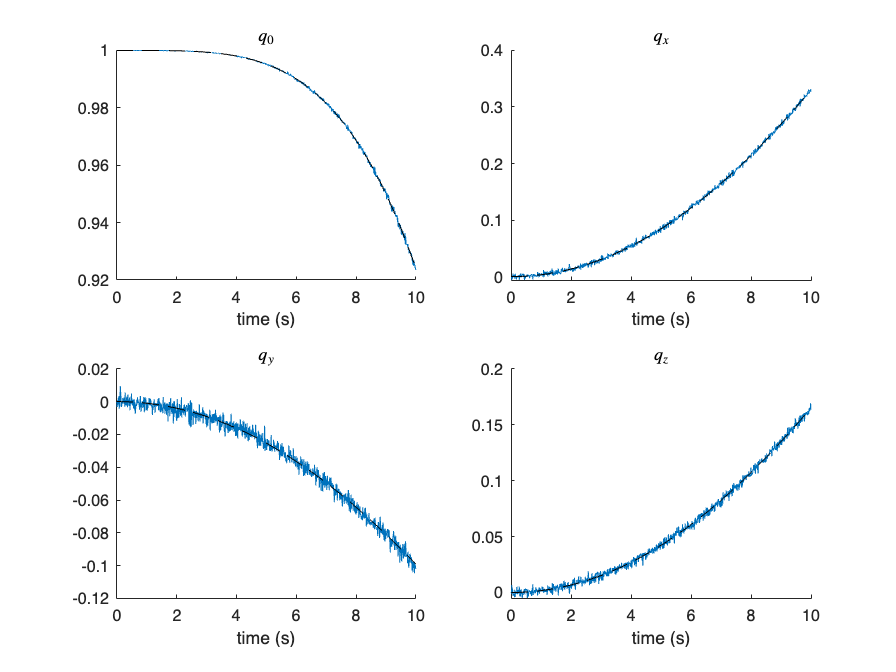

IMU = imuSensor("IMUType","accel-mag");    %initialise IMU that has an accelerometer and magnetometer
IMU.Accelerometer.NoiseDensity = 0.00851;    %set accelerometer noise
IMU.Magnetometer.NoiseDensity = 0.01281;    %set magnetometer noise

acceleration = 0;    %set translation acceleration experienced by IMU

dT = 0.01;    %sampling time of IMU
numSamples = 1000;    %number of samples
t = (0:numSamples-1)*dT;    %define time vector for plotting

v = [1 -0.3 .5];    %arbitrary rotation vector (not necessarily normalised)
v = v/norm(v);      %normalise rotation vector
omega = linspace(0,pi/20,numSamples);    %angular velocity magnitude
q = zeros(numSamples,4);    %initialised quaternion array
q(1,1:4) = [1 0 0 0];

q_ = zeros(numSamples,4);    %initialised quaternion estimate array
q_(1,1:4) = [1 0 0 0];

gw = [0 0 1];    %gravity vector in {W}
mw = IMU.MagneticField;    %magnetometer vector in {W}

sw = cross(gw,mw);    %cross product of gravity vector and magnetic intensity vector
sw = sw/norm(sw);     %normalised form

zw = cross(gw,sw);    %cross product of gravity vector and new vector above
zw = zw/norm(zw);     %normalised form

for k=1:numSamples-1

    %true orientation
    alpha = omega(k)*dT;    %rotation angle at sample instance k
    theta = alpha*v;        %exponential coordinate at sample instance k
    dq = [cos(alpha/2) sin(alpha/2)*v];    %incremental quaternion
    q(k+1,:) = quatmultiply(q(k,:),dq);    %updated quaternion

    R = quat2rotm(q(k+1,1:4));    %convert quaternion to rotation matrix

    %measurement
    [accel_meas,mag_meas] = IMU(acceleration*ones(1,3),omega(k)*v,R');    %generate accelerometer and magnetometer data
    ab = accel_meas/norm(accel_meas);    %normalised accelerometer data
    mb = mag_meas/norm(mag_meas);    %normalised magnetometer data
    
    sb = cross(ab,mb);    %calculate cross product of accelerometer and magnetometer readings
    sb = sb/norm(sb);     %normalise
    
    zb = cross(ab,sb);    %calculate cross product of accelerometer reading and sb
    zb = zb/norm(zb);     %normalise

    C = [ab' sb' zb'];    %populate matrix C with measurements in {B}
    A = [gw' sw' zw'];    %populate matrix A with observations in {W}

    R_ = A*C';            %estimate rotation matrix 
    
    q_(k+1,:) = rotm2quat(R_);    %convert rotation matrix to quaternion
end

%plot figure
figure
subplot(2,2,1),hold on
plot(t,q_(:,1)),plot(t,q(:,1),'--k'),title('$q_0$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,2),hold on
plot(t,q_(:,2)),plot(t,q(:,2),'--k'),title('$q_x$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,3),hold on
plot(t,q_(:,3)),plot(t,q(:,3),'--k'),title('$q_y$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,4),hold on
plot(t,q_(:,4)),plot(t,q(:,4),'--k'),title('$q_z$',Interpreter='latex'),xlabel('time (s)')

### 4.4.2 Complementary filter

Section 4.4.3 will introduce the explicit complementary filter, which is a powerful method of estimating orientation when both vector observations and gyroscope data is available. However, before diving into that, it is useful to first step back and understand the principle of the linear complementary filter. Given any arbitrary signal, one can recover the signal after passing it through a low-pass and high-pass filter with matching order and cutoff frequency. By example, it is easy to show that input signal $U(s)$ when passed through a first-order low-pass filter and high-pass filter with cutoff frequency of $a$ rad/s, followed by summing, yields the original signal:


$$\begin{array}{ll}
Y(s)
&=\frac{1}{1+s/a}U(s)+\frac{s/a}{1+s/a}U(s),\\
&=\left(\frac{1}{1+s/a}+\frac{s/a}{1+s/a}\right)U(s),\\
&=\frac{1+s/a}{1+s/a}U(s),\\
&= U(s).
\end{array}$$


Note that we are using transfer functions to understand the signal behaviour above, with $s$ denoting the Laplace operator.

We can exploit the complementary relationship above to determine an esimate that is derived from filtering and then summing two *different* sensor measurements, using a low-pass and high-pass filter. The reasoning for this is that sensors often have appealing characteristics in a particular frequency range but undesirable characteristics in other ranges. In this case, we can try and filter measurements so that only the best qualities of a measurement are retained. 

Consider an IMU that is constrained such that it can only roll about $\hat{\bf x}_W$. In this case, we can obtain an estimate of the orientation from the gyroscope (after integration), and an estimate of the orientation from the accelerometer. As shown previously, the orientation estimate from the gyroscope works well initially but has the problem of drifting over time, as a result of the accumulation of measurement error, paired with integration error. As such, orientation estimation using just the gyroscope has good high-frequency characteristics but poor low-frequency characteristics. The orientation estimate from the accelerometer contains a lot of high-frequency noise due to the nature of the sensor, but at low frequencies it behaves reliably. These two sensors therefore have good complementary properties and we can use them in a complementary filter to extract their usable frequency ranges.

Referring to the equation above, if the orientation estimate from the gyroscope and accelerometer are expressed in the Laplace domain as $\Theta^+_g(s)$ and $\Theta^+_a(s)$, respectively, the complementary filter to estimate orientation about a single axis can be expressed as


$$\begin{array}{ll}
\Theta^+(s)
&=\frac{1}{1+s/a}\Theta^+_a(s)+\frac{s/a}{1+s/a}\Theta^+_g(s).\\
\end{array}$$


The cutoff frequency of $a$ needs to be selected carefully to make use of the best ranges of both sensor readings and is often tuned using trial and error. The multi-input transfer function above can be represented in block diagram form as

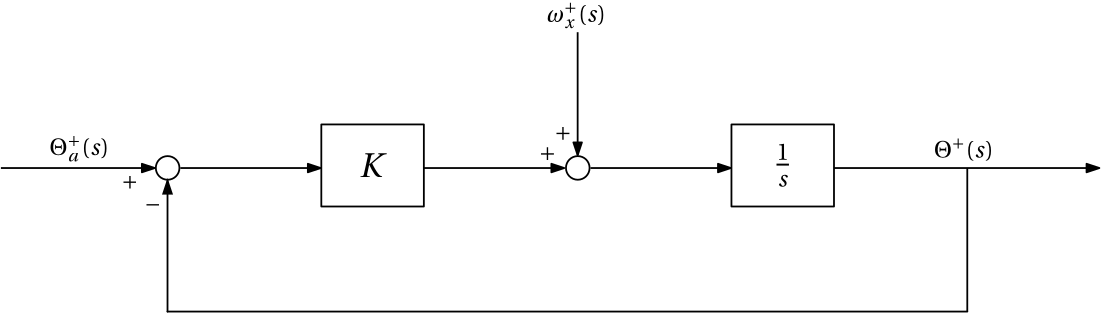

**Figure 4.2: **Block diagram of a 1-dimensional complementary filter that uses gyroscope and accelerometer information.

where $K=\frac{1}{a}$ and $\omega^+_x(s)=s\Theta^+_g(s)$ is the angular velocity estimate from the gyroscope.

### 4.4.3 Explicit complementary filter

The explicit complementary filter is a multivariate, nonlinear version of the complementary filter. This approach exploits the complementary nature of the different measurements that are available on the robot. The formulation follows a similar methodology to that outlined in Section 4.2.1.3 and Section 4.2.1.4, which are both predicated on determining the incremental exponential coordinates, before encoding this information in a rotation matrix or quaternion vector.

The objective is to first define an orientation error using vector measurements (for example, from an accelerometer and/or magnetometer) and the current orientation estimate, and then use this information to sequentially correct the orientation estimate from the gyroscope. 

We will first begin using just an accelerometer and gyroscope, and then later also include a magnetometer into the fusion scheme.

#### 4.4.3.1 Orientation error

We start by defining the unit-normalised accelerometer measurement at sample instance $k$ as 


$${^B\hat{\bf a}_k^\#}=\frac{{^B{\bf a}_k^\#}}{|{^B{\bf a}_k^\#}|},$$
 

which is equal to the normalised body-frame gravity vector (when translation acceleration is negligible), namely ${^B\hat{\bf a}^\#_k}\approx{^B\hat{\bf g}_k}$. We also know that the gravitational vector in $\{W\}$ after normalisation is given by${^W\hat{\bf g}}=[0~0~1]^T$. Using the representations above, and considering the geometric meaning of the cross product as shown in **Chapter 3**, we can (approximately) determine the orientation error at sample instance $k$ based on


$$\begin{array}{ll}
^B{\bf\sigma} _k
&\approx  {^B\hat{\bf a}^\#_k} \times {^B\hat{\bf g}^+_} ,\\
&\approx {^B\hat{\bf a}^\#_k} \times \left({^B{\bf R}^+_{W_k}}{^W\hat{\bf g}}\right)   .
\end{array}$$


Note that this approximation is suitable when the angle between the two vectors is suitably small, which should be the case if the system is initialised with the correct starting orientation. 

As previously mentioned, the cross product generates a rotational error about an axis perpendicular to ${^B\hat{\bf a}^\#_k}$ and ${^B\hat{\bf g}^+_}$. If $ {^B\hat{\bf a}^\#_k} \times {^B\hat{\bf g}^+_}=0$, the current gravity estimate in $\{B\}$ is correct, which implies that the rotation matrix estimate, ${^W{\bf R}^+_{B_k}}$, is correct (up to ambiguous orientation about $\hat{\bf z}_W$).

#### 4.4.3.2 Updated incremental orientation

Recall that the incremental rotation matrix at sample instance $k$, compiled from an estimated angular velocity estimate over sample period $\Delta t$ is given by


$$\begin{array}{ll}
\Delta{\bf R}^+_k
&={^{\{k-1\}}{\bf R}^+_{\{k\}},\\
&=\mathrm{\bf e}^{\lfloor {^B{\bf \omega}^+_k}\Delta t \rfloor},\\
&=\mathrm{\bf e}^{\lfloor {^B{\bf \omega}^+_k} \rfloor\Delta t}.\\
\end{array}
$$


This incremental rotation obtained from the gyroscope reading alone had the problem of not being reliable in the long term, as a result of integrated sensor drift. The explicit complementary filter accounts for this by appending the orientation error from Section 4.4.3.1 to the incremental exponential coordinates that are to be integrated, namely


$$\begin{array}{ll}
{^{\{k-1\}}{\bf R}^+_{\{k\}}

=\mathrm{\bf e}^{\lfloor {^B{\bf \omega}^+_k}+K{^B{\bf \sigma}_k} \rfloor\Delta t},

\end{array}
$$


where $K>0$ is a gain term that is inversely related to the cutoff frequency of the complementary filter and can be used to adjust priority between the accelerometer and gyroscope measurements. As before, the orientation with respect to an inertial frame of reference, such as $\{W\}$, is obtained using


$$\begin{array}{ll}
{^W{\bf R}^+_{\{k\}}}
&={^W{\bf R}^+_{\{0\}}}{^{\{0\}}{\bf R}^+_{\{1\}} \dots {^{\{k-1\}}{\bf R}^+_{\{k\}},\\
&={^{W}{\bf R}^+_{\{k-1\}} {^{\{k-1\}}{\bf R}^+_{\{k\}},\\
\end{array}$$
 

where ${^{W}{\bf R}^+_{\{k-1\}}$ represents the orientation estimate at the previous sampling instance before being updated by incremental rotation matrix $k$.

If the innovation term $K{^B{\bf\sigma} _k}$ is zero, the incremental orientation only uses gyroscope information for future estimates, implying that the measurements from the gyroscope are "trustworthy". However, if the orientation error is nonzero, as a result of an imperfect orientation estimate, the gyroscope measurement is supplemented by the scaled orientation error to correct it. This structure can be thought of as a feedback loop, where (open-loop) feedforward estimates of orientation from the angular velocity are improved by a feedback structure comparing the estimated and true gravity vectors in $\{B\}$. The equivalent block diagram formulation is shown in Figure 4.3 below.

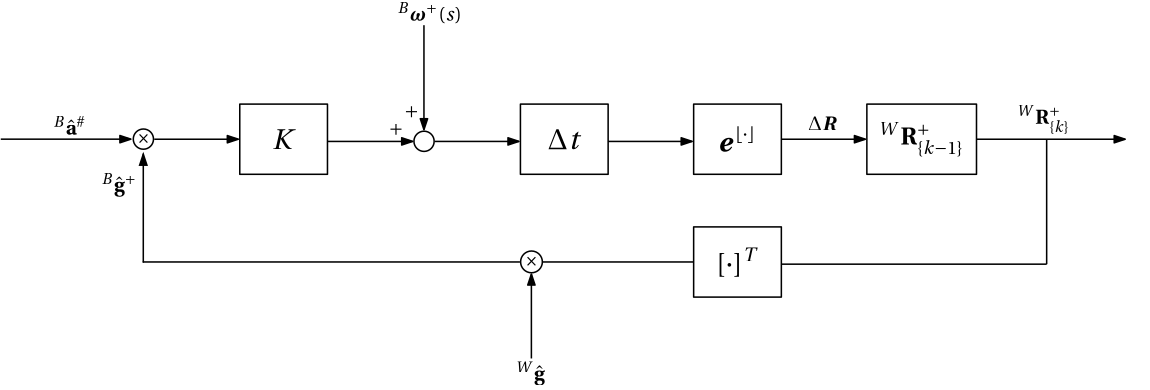

**Figure 4.3: **Block diagram of a 3-dimensional explicit complementary filter that uses gyroscope and accelerometer information.

With the appropriate gain term of $K$, the estimation scheme will output a reliable estimate for rotation vectors within in the $\hat{\bf x}_W$-$\hat{\bf y}_W$ plane. Based on the description above, we can deduce that:

- decreasing $K$ places more trust in the gyroscope reading, as the innovation term becomes smaller;

- increasing $K$ places more trust in the accelerometer reading, as the angular rate measurement is augmented with a larger innovation term.

In the frequency domain, this can be thought of as adjusting the effective cut-off frequency of the gyroscope high-pass filter and accelerometer low-pass filter.

We still unfortunately cannot reliably estimate rotations about $\hat{\bf z}_W$, based on the fact that ${^W{\bf g}}=[0~0~1]^T$ is always perpendicular to $\hat{\bf z}_W$ and cannot detect such rotations.

The quaternion counterpart, after including the innovation term, is given by


$$\begin{array}{cc}\Delta{\mathbf q}^+_k =
{^{\{k-1\}}{\bf q}^+_{\{k\}}
= \left[\begin{array}{cc}    \cos{\frac{\alpha^+_k}{2}} \\ \sin{\frac{\alpha^+_k}{2}} {^B\hat{\mathbf v}^+_k}     \\ \end{array}\right],\end{array}$$


where 


$$\alpha_k^+=\left|{^B{\bf \omega}^+_k}+K{^B{\bf \sigma}_k}\right|\Delta t,$$


and


$${^B\hat{\mathbf v}^+_k}=\frac{\left({^B{\bf \omega}^+_k}+K{^B{\bf \sigma}_k}\right)\Delta t}{\alpha_k^+}.$$


The absolute quaternion, determined with respect to $\{W\}$ for example, is then derived using quaternion multiplication as


$$\begin{array}{ll}
{^W{\bf q}^+_{\{k\}}}
&={^W{\bf q}^+_{\{0\}}}\otimes{^{\{0\}}{\bf q}^+_{\{1\}}\otimes \dots \otimes{^{\{k-1\}}{\bf q}^+_{\{k\}}, \\
&={^W{\bf q}^+_{\{k-1\}}} \otimes{^{\{k-1\}}{\bf q}^+_{\{k\}}.
\end{array}$$
 

#### Example: Estimating orientation using gyroscope and accelerometer readings

The code block below shows an example of how accelerometers and gyroscopes can be used together to partially estimate orientation. 

We should notice that:

- increasing the accelerometer or magnetometer noise density results in a noiser estimate, but the mean behaviour is still correct;

- lack of compensation of the yaw rotation means that the yaw estimate will drift over time (as seen in the plot for $q_z$), with a rate proportional to the gyroscope noise density;

- increasing $K$ value places more trust in the accelerometer measurements;

- decreasing $K$ value places more trust in the gyroscope measurements;

- increasing the translational acceleration causes problems in the estimation scheme, based on the assumption that the accelerometer is only detecting the gravitational vector.

IMU = imuSensor("IMUType","accel-gyro");     %initialise IMU with gyroscope and accelerometer
IMU.Accelerometer.NoiseDensity = 0.00001;    %set acclerometer noise density
IMU.Gyroscope.NoiseDensity = 0.02491;    %set gyroscope noise density
acceleration = 0;    %set translation acceleration experienced by IMU

 K = 6;    %set complementary filter gain

dT = 0.01;    %sample time
numSamples = 1000;    %number of samples
t = (0:numSamples-1)*dT;

v = [1 1 0];
v = v/norm(v);    %rotation vector
omega = linspace(0,pi/20,numSamples);
q = zeros(numSamples,4);
q(1,1:4) = [1 0 0 0];

q_ = zeros(numSamples,4);
q_(1,1:4) = [1 0 0 0];
q = q_;

gw = [0 0 1];    %gravity vector in {W}

for k=1:numSamples-1

    %true orientation
    alpha = omega(k)*dT;
    theta = alpha*v;
    dq = [cos(alpha/2) sin(alpha/2)*v];
    q(k+1,:) = quatmultiply(q(k,:),dq);

    R = quat2rotm(q(k+1,1:4));

    %measurement
    [accel_meas,gyro_meas] = IMU(acceleration*ones(1,3),omega(k)*v,R');
    accel_meas = accel_meas/norm(accel_meas);
    mag_meas = mag_meas/norm(mag_meas);

    %orientation error
    R_ = quat2rotm(q_(k,:));
    gb_ = R_'*gw';
    sigma = cross( accel_meas',gb_ );

    %estimate
    theta_ = (gyro_meas+K*sigma')*dT;
    alpha_ = norm(theta_);
    if( alpha_ == 0)
        v_ = [0 0 0];
    else
        v_ = theta_/alpha_;
    end

    dq_ = [cos(alpha_/2) sin(alpha_/2)*v_];
    q_(k+1,:) = quatmultiply( q_(k,:),dq_ );
    
end
%plot figure
figure
subplot(2,2,1),hold on
plot(t,q_(:,1)),plot(t,q(:,1),'--k'),title('$q_0$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,2),hold on
plot(t,q_(:,2)),plot(t,q(:,2),'--k'),title('$q_x$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,3),hold on
plot(t,q_(:,3)),plot(t,q(:,3),'--k'),title('$q_y$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,4),hold on
plot(t,q_(:,4)),plot(t,q(:,4),'--k'),title('$q_z$',Interpreter='latex'),xlabel('time (s)')

#### 4.4.3.3 Orientation error with multiple vector measurements

If we are interested in reliably estimating the full 3D orientation, we would require an additional vector measurement that is not parallel to $\hat{\bf z}_W$. We have already shown that the magnetometer fits this requirement. We can update our orientation error formulation to take in any number of vectorial measurements, based on


$$\begin{array}{ll}
^B{\bf\sigma} _k
&= \sum_i^N {^B\hat{\bf v}^\#_i} \times {^B\hat{\bf v}^+_{i_k}},\\
&=\sum_i^N {^B\hat{\bf v}^\#_i} \times\left({^B{\bf R}^+_{W_k}}{^W\hat{\bf v}_i}\right)   ,
\end{array}$$


where $i$ corresponds to the particular vector measurement instance, ${^W\hat{\bf v}_i}$ is the known value of vector observiation $i$ in $\{W\}$, and ${^B\hat{\bf v}_{i_k}^+}$ is the corresponding estimate in $\{B\}$ at sample instance $k$. For the case of an accelerometer and magnetometer, this reduces to


$$\begin{array}{ll}
{\bf\sigma} _k
&= \sum_i^N {^W\hat{\bf v}_i} \times {^W\overline\hat{\bf v}_{i_k}},\\
&= {^W\hat{\bf g}_} \times {^W\overline\hat{\bf g}_k}+{^W\hat{\bf m}_} \times {^W\overline\hat{\bf m}_k}.\\
\end{array}$$


Note that one could also allocate disparate gains to the orientation error generated from the accelerometer and magnetometer vectors, such as 


$$\begin{array}{ll}
{\bf\sigma} _k
&= K_g{^W\hat{\bf g}_} \times {^W\overline\hat{\bf g}_k}+K_m{^W\hat{\bf m}_} \times {^W\overline\hat{\bf m}_k},
\end{array}$$


where $\{K_g,K_m\}>0$ are adjustable terms to allocate trustworthiness between the accelerometer and magnetometer. This is useful if one of the sensors is less reliable than the others, such as when translational acceleration is experienced.

#### Example: Estimating orientation using gyroscope, accelerometer, and magnetometer readings

The code block below shows an example of how accelerometers, magnetometers, and gyroscopes can be used together to fully estimate orientation. 

We should notice that:

- increasing the accelerometer or magnetometer noise density results in a noiser estimate, but the mean behaviour is still correct;

- yaw estimation is now reliable, thanks to the inclusion of the magnetometer readings;

- increasing $K$ value places more trust in the accelerometer and magnetometer measurements;

- decreasing $K$ value places more trust in the gyroscope measurements;

- increasing the translational acceleration causes problems in the estimation scheme, based on the assumption that the accelerometer is only detecting the gravitational vector.

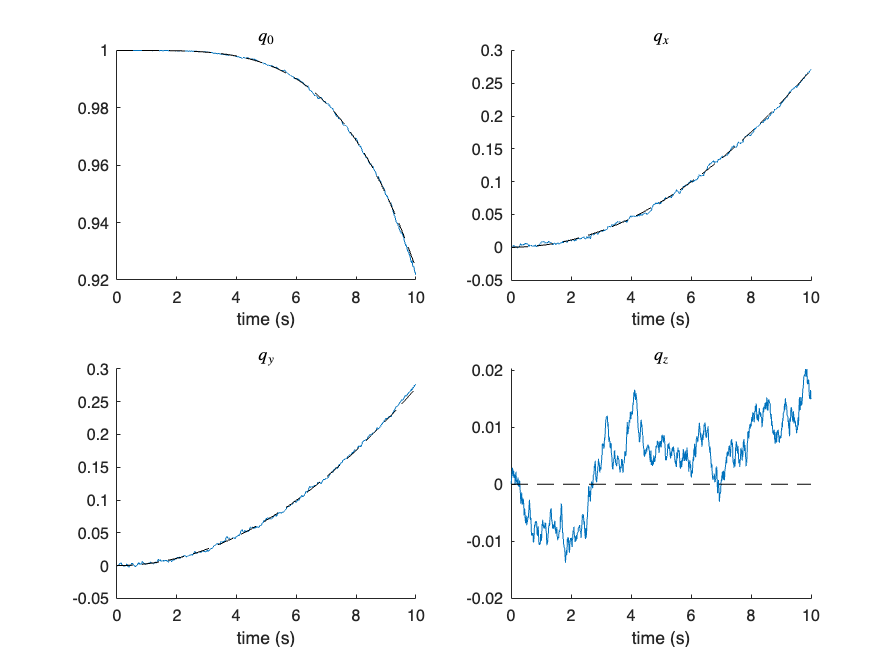

IMU = imuSensor(IMUType="accel-gyro-mag");
IMU.Accelerometer.NoiseDensity = 0.00651;
IMU.Magnetometer.NoiseDensity = 0.00811;
IMU.Gyroscope.NoiseDensity = 0.02491;

acceleration =0;    %set translation acceleration experienced by IMU

K = 6;


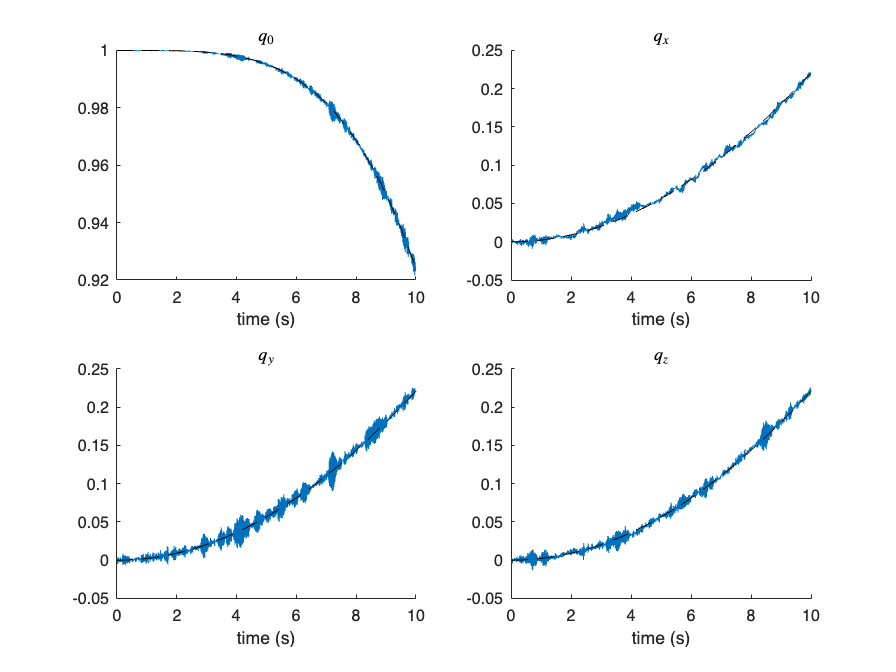

dT = 0.01;
numSamples = 1000;
t = (0:numSamples-1)*dT;

v = [1 1 1];
v = v/norm(v);
omega = linspace(0,pi/20,numSamples);
q = zeros(numSamples,4);
q(1,1:4) = [1 0 0 0];

q_ = zeros(numSamples,4);
q_(1,1:4) = [1 0 0 0];
q = q_;

gw = [0 0 1];
mw = IMU.MagneticField;    %magnetometer vector in {W}

for k=1:numSamples-1

    %true orientation
    alpha = omega(k)*dT;
    theta = alpha*v;
    dq = [cos(alpha/2) sin(alpha/2)*v];
    q(k+1,:) = quatmultiply(q(k,:),dq);

    R = quat2rotm(q(k+1,1:4));

    %measurement
    [accel_meas,gyro_meas,mag_meas] = IMU(acceleration*ones(1,3),omega(k)*v,R');
    accel_meas = accel_meas/norm(accel_meas);
    mag_meas = mag_meas/norm(mag_meas);

    %orientation error
    R_ = quat2rotm(q_(k,:));
    gb_ = R_'*gw';
    mb_ = R_'*mw';
    sigma = cross( accel_meas',gb_ )+cross( mag_meas',mb_ );

    %estimate
    theta_ = (gyro_meas+K*sigma')*dT;
    alpha_ = norm(theta_);
    if( alpha_ == 0)
        v_ = [0 0 0];
    else
        v_ = theta_/alpha_;
    end

    dq_ = [cos(alpha_/2) sin(alpha_/2)*v_];
    q_(k+1,:) = quatmultiply( q_(k,:),dq_ );
    
end
%plot figure
figure
subplot(2,2,1),hold on
plot(t,q_(:,1)),plot(t,q(:,1),'--k'),title('$q_0$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,2),hold on
plot(t,q_(:,2)),plot(t,q(:,2),'--k'),title('$q_x$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,3),hold on
plot(t,q_(:,3)),plot(t,q(:,3),'--k'),title('$q_y$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,4),hold on
plot(t,q_(:,4)),plot(t,q(:,4),'--k'),title('$q_z$',Interpreter='latex'),xlabel('time (s)')